% Experiment 5 - Restnet 
% Author: Akshay.R 

close all;
clear variables;
existing_GUIs = findall(0);
if length(existing_GUIs) > 1
    delete(existing_GUIs);
end
clc;

## Read the image data from the relevant text files.

folder = "/Users/akshay/Desktop/ASS/CUB_200_2011_Subset20classes/";
imgFolder = folder + "images/";
imgTxtFolder = folder + "images.txt";

% Load in all images from the dataset folder into one datastore
allImageDS = imageDatastore(imgFolder, 'IncludeSubfolders', true, ...
                            'LabelSource','foldernames');

## Split dataset into five folds (=partitions) for fivefold cross-validation.

[fold1DS, fold2DS, fold3DS, fold4DS, fold5DS] = ...
    splitEachLabel(allImageDS, 0.2, 0.2, 0.2, 0.2);

% Set target size for common width and height after cropping
targetSize = [224, 224];

% Number of folds is five in this experiment
numFolds = 5;

## Check if we have a GPU available and clear any old data from it

if (gpuDeviceCount() > 0)
    device = gpuDevice(1);
    reset(device);  % Clear previous values that might still be on the GPU
end

## Train the Resnet50 model for each fold

Accuracy for Run 177 is: 0.88


Accuracy for Run 177 is: 0.88


Accuracy for Run 177 is: 0.88688


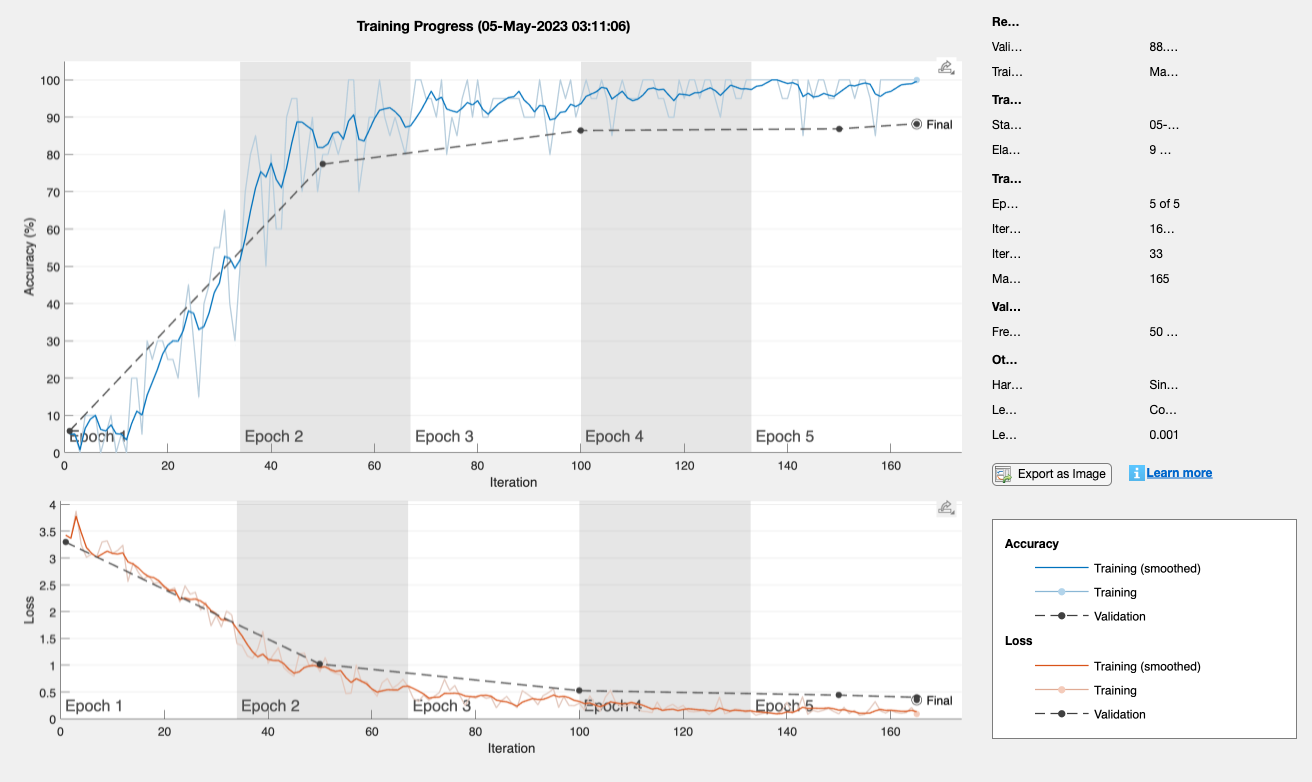

Accuracy for Run 177 is: 0.88789


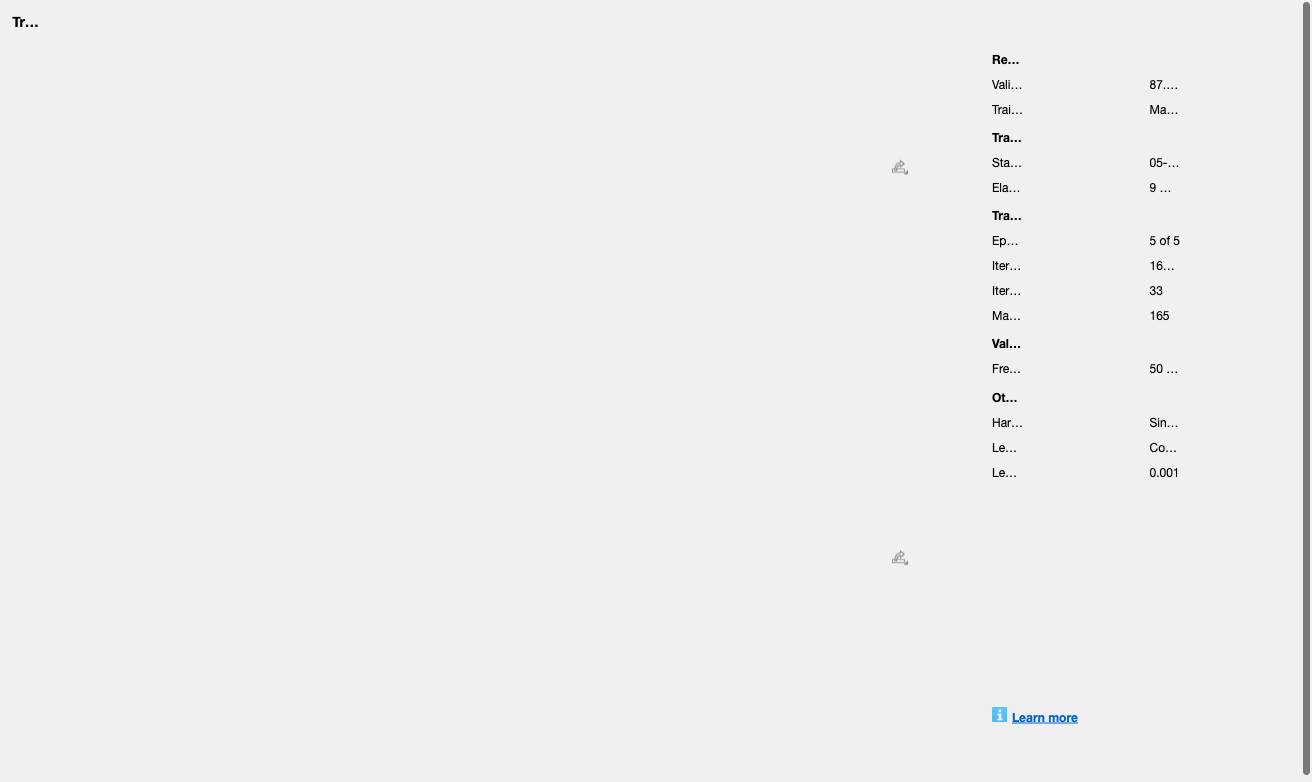

Accuracy for Run 177 is: 0.93665


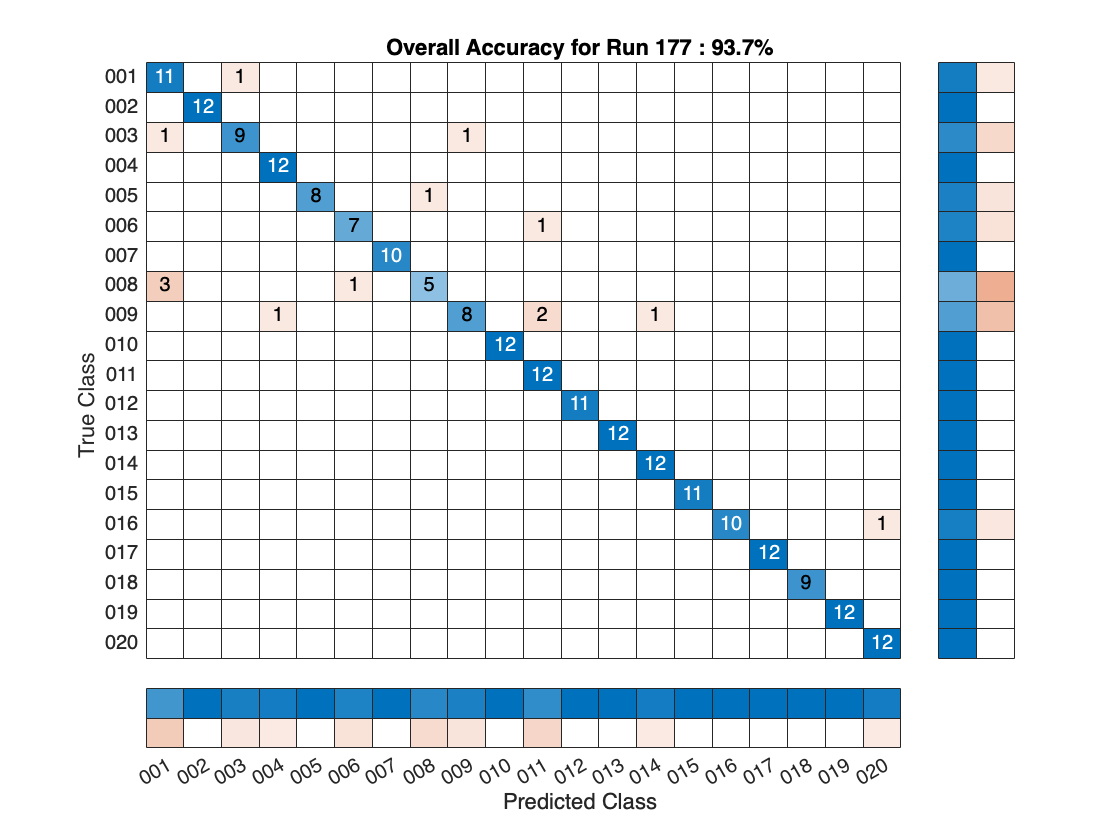

accuracy_overall = 0.0;
for i = 1:numFolds
    [augmentedTrainingImageDS, validationImageDS_Resized, testImageDS_Resized, trainingImageDS, ...
        validationImageDS, testImageDS] = ...
        getFoldsFor5FoldCrossVal(i, fold1DS, fold2DS, fold3DS, fold4DS, ...
                                 fold5DS, folder, imgTxtFolder, targetSize);

    % Set the restnet training options
    net = resnet50;
    inputSize = net.Layers(1).InputSize;
    lgraph = layerGraph(net);

    numClasses = numel(categories(trainingImageDS.Labels));
    newFcLayer = fullyConnectedLayer(numClasses, 'Name', 'new_fc');
    lgraph = replaceLayer(lgraph, 'fc1000', newFcLayer);

% Find the classification layer's name
classificationLayerName = '';
for i = 1:numel(net.Layers)
    if isa(net.Layers(i), 'nnet.cnn.layer.ClassificationOutputLayer')
        classificationLayerName = net.Layers(i).Name;
        break;
    end
end

newClassLayer = classificationLayer('Name', 'new_classoutput');
lgraph = replaceLayer(lgraph, classificationLayerName, newClassLayer);
    options = trainingOptions('sgdm', ...
        'InitialLearnRate', 0.001, ...
        'MiniBatchSize', 20, ...
        'MaxEpochs', 5, ...
        'Verbose', false, ...
        'Shuffle', 'every-epoch', ...
        'VerboseFrequency', 1, ...
        'ValidationData', validationImageDS_Resized, ...
        'Plots','training-progress');

    restnet = trainNetwork(augmentedTrainingImageDS, lgraph, options);

    YPred = classify(restnet, testImageDS_Resized);
    YTest = testImageDS.Labels;
    
    accuracy = sum(YPred == YTest)/numel(YTest); % Output on command line
    disp("Accuracy for Run "+ string(i)+" is: " + accuracy);

    % Show confusion matrix in figure
    [m, order] = confusionmat(YTest, YPred);
    figure(i);
    cm = confusionchart(m, order, ...
        'ColumnSummary','column-normalized', ...
        'RowSummary','row-normalized');
    title("Overall Accuracy for Run "+ string(i)+" : "+ ...
        string(round(accuracy*100, 1)) +"%");

    accuracy_overall = accuracy_overall+accuracy;
end

disp("Average accuracy of five folds is "+ string(accuracy_overall/numFolds))

Average accuracy of five folds is 0.89428
